*Copyright 2025 The MathWorks, Inc.*

# **EXERCISE 1 : Simulate the Simplest 5G Network**

#    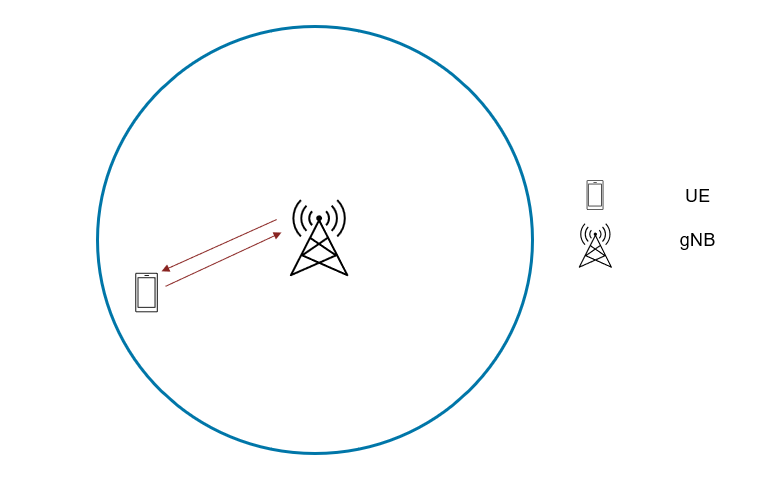

This exercise demonstrates the workflow of 5G NR network simulation with one gNB (base station) and one UE (user equipment).

The objectives are to:

- Understand how to create and configure gNB and UE nodes 

- Set up a 5G network 

- Simulate the network, measure KPIs, and capture statistics 

- Explore visualization tools 

The following figure shows the different layers of an NR nodes that can be modeled in MATLAB.  

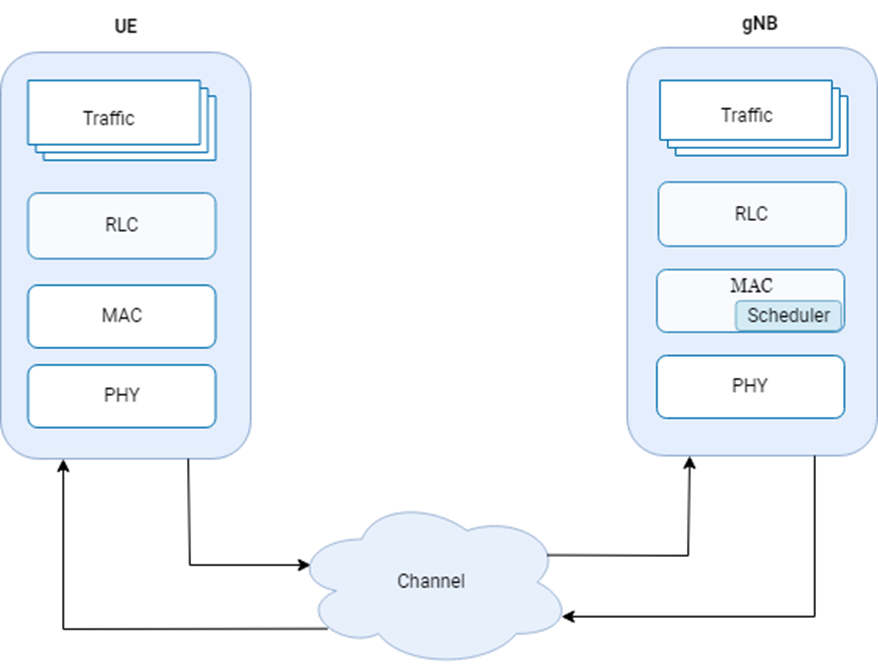

#### Close any previously opened figures 

- Close all previous windows

- Reset the random number generator for reproducibility

all_figs = findall(0, 'type', 'figure');close(all_figs); 
rng("default")  

#### Initialize Variables and Wireless Network Simulator

- Initialize the Wireless Network Simulator

- Number of frames to simulate and simulation time in seconds 

- Launch the wireless network viewer to visualize the network during simulation

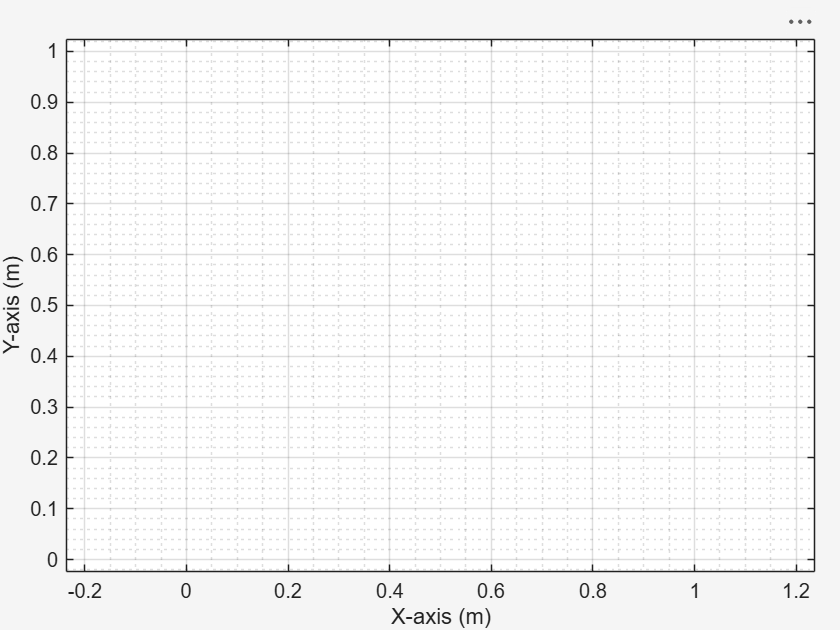

networkSimulator = wirelessNetworkSimulator.init;
numFrameSimulation = 30; simulationTime = numFrameSimulation*0.01; 
viewerObj = wirelessNetworkViewer();

# Task 1/7: Create a 5G base station 

**Description of the task**

Model a 5G base station by configuring the physical and MAC layer parameters and specifying its position [x,y,z] in Cartesian coordinates (meters).

- Support both SISO and MIMO antenna configurations as per 3GPP specifications 

- Configure subcarrier spacing (SCS), up to: 120 kHz 

- Configure channel bandwidth, up to: 400 MHz

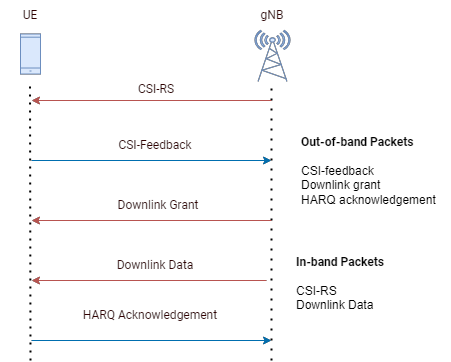

**DL Transmission**

Downlink (DL) transmission workflow:

- The gNB (Next Generation Node B) sends CSI-RS (Channel State Information Reference Signals) for channel estimation 

- The UE (User Equipment) estimates the channel and reports CSI (Channel State Information) feedback: 

- PMI (Precoding Matrix Indicator)

- RI (Rank Indicator)

- CQI (Channel Quality Indicator)

- The gNB uses this feedback to schedule DL transmission (modulation and coding scheme, number of layers, etc.) 

- DL data is transmitted to the UE 

- The UE sends a HARQ (Hybrid Automatic Repeat Request) acknowledgment (ACK/NACK) based on reception

**Instructions to complete the task**

Use` nrGNB() `function to create a NR base station 

Store NR base station in a variable named "gNB"

Hint:type `doc nrGBN`  in command window and see the "Syntax" section.

Note : use the following values as arguments 

-     "Name","gNB"

-     "Position",gNBPosition

-     "SubcarrierSpacing",15000

-     "CarrierFrequency",2.6e9

-     "ChannelBandwidth",5e6

-     "NumTransmitAntennas",numTxAntenna

-     "NumReceiveAntennas",numRxAntenna

-     "PHYModel",phyAbstraction

gNBPosition = [0 0 30]; 
phyAbstraction = "full-phy";
numTxAntenna = 1;
numRxAntenna = 1;

% Write your code here
gNB = nrGNB("Name","gNB", ...
    "Position",gNBPosition, ...
    "SubcarrierSpacing",15000, ...
    "CarrierFrequency",2.6e9, ...
    "ChannelBandwidth",5e6, ...
    "NumTransmitAntennas",numTxAntenna, ...
    "NumReceiveAntennas",numRxAntenna, ...
    "PHYModel",phyAbstraction);

####  Visualize the 5G base station in the Network Viewer 

Add node to the network viewer for visualization 

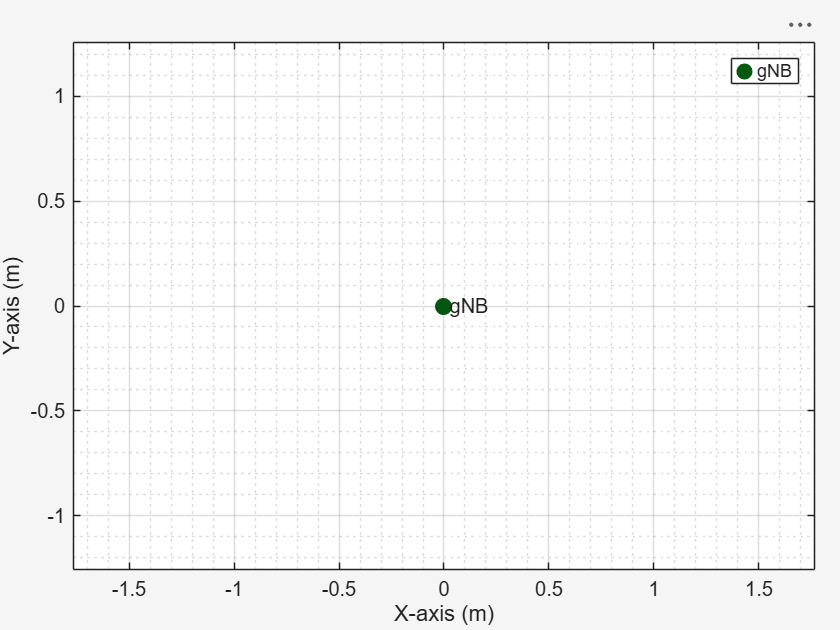

addNodes(viewerObj,gNB,Type="gNB");

# Task 2/7: Create a NR user equipment  

**Description of the task**

Model a 5G user equipment (UE) by configuring the physical and MAC layer parameters and specifying its position [x,y,z] in Cartesian coordinates (meters).

- Support both SISO and MIMO antenna configurations (up to 4 antennas) 

- Use the same physical (PHY) layer abstraction method as the gNB

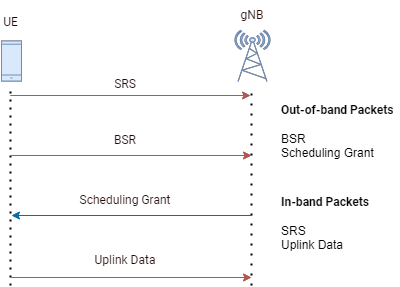

Uplink (UL) transmission workflow:

- UE sends SRS (Sounding Reference Signals) for channel estimation 

- gNB estimates UL CSI and determines parameters (TPMI, RI, MCS) 

- UE sends BSR (Buffer Status Report) to indicate data to transmit 

- gNB provides a scheduling grant

- UE transmits UL data over PUSCH (Physical Uplink Shared Channel)

**Instructions to complete the task**

Use `nrUE()` function to create a 5G user equipment (UE) 

Store NR base station in a variable named "UE"

Hint: type `doc nrUE` in command line, and see the "Syntax" section.

Note : use the following values as arguments 

- "Name",ueName

- "Position",uePosition

- "NumReceiveAntennas",numRxAntenna

- "NumTransmitAntennas",numTxAntenna

- "PHYModel",phyAbstraction

ueName = ["UE-1"]; 
uePosition = [300 0 1.5];
numTxAntenna = 1;
numRxAntenna = 1;

% Write your code here
UE = nrUE("Name",ueName, ...
    "Position",uePosition, ...
    "NumReceiveAntennas",numRxAntenna, ...
    "NumTransmitAntennas",numTxAntenna, ...
    "PHYModel",phyAbstraction);

####  Visualize the 5G user equipment in the Network Viewer 

Add node to the network viewer for visualization 

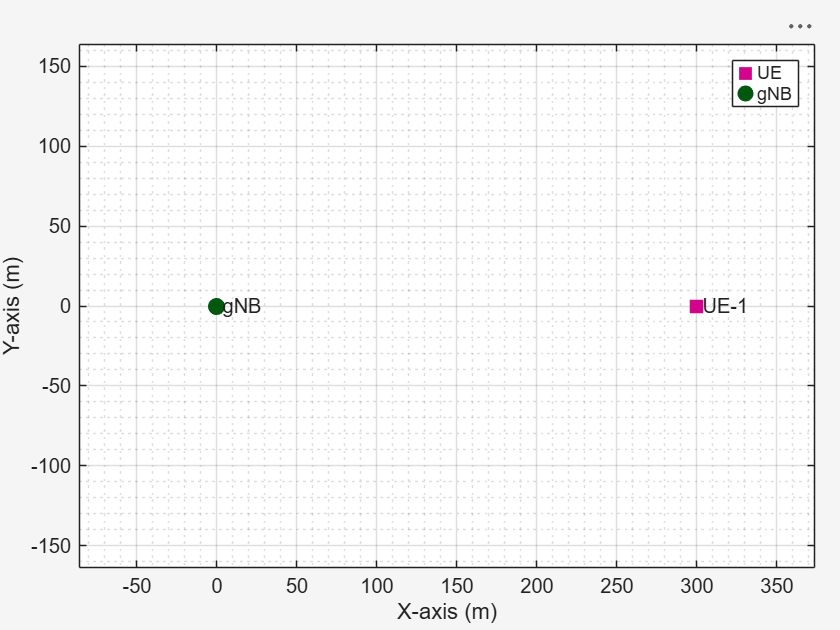

addNodes(viewerObj,UE,Type="UE");

# Task 3/7: Create the 5G network   

**Description of the task**

Connect UE(s) to the gNB 

**Instructions to complete the task**

Use connectUE() function to connect gNB to corresponding UEs

Hint: type `doc connectUE`, and see the "Syntax" section.

Note : use the following values as arguments 

- gNB

- UE

% <enter code below>
connectUE(gNB,UE);

# Task 4/7: Create a traffic model 

**Description of the task**

Application Traffic Pattern Modeling

- On-Off Traffic (Periodic, Bursty, or Random) – Represents intermittent data transmission patterns with varying activity periods.

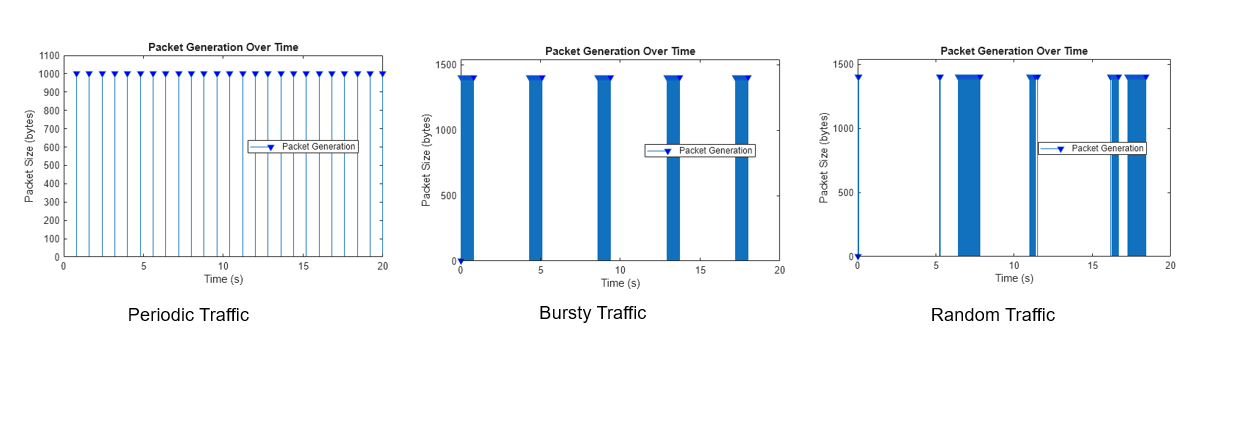

Other supported application traffic models 

- FTP (File Transfer Protocol) – Models file-based data transfer sessions.

- Video Streaming – Simulates continuous media flow with variable bit rates.

- Voice over IP (VoIP) – Models real-time voice communication traffic.

**Instructions to complete the task**

Use networkTrafficOnOff() function to configure application layer traffic. 

Write configuration in a variable named "traffic". 

Type "doc networkTrafficOnOff" in the MATLAB Command Window, and see the "Syntax" section.

Note : use the following values as arguments, data rate is in kbps and packet size is in Bytes, time is in seconds  

- "DataRate",40e3

- "OnTime",simulationTime

- "OffTime",0

Note that traffic throughout the simulation time does not necessarily mean continuous traffic. This models periodic traffic, where the transmission periodicity is determined by the configured data rate and packet size.

% <enter code below>
traffic =  networkTrafficOnOff("DataRate",32e3, ...
    "OnTime",simulationTime, ...
    "OffTime",0);

#### Visualize the configured traffic pattern 

Time: 0.000375 s - Generated a periodic packet_1 of size 1500 bytes
Time: 0.000750 s - Generated a periodic packet_2 of size 1500 bytes
Time: 0.001125 s - Generated a periodic packet_3 of size 1500 bytes
Time: 0.001500 s - Generated a periodic packet_4 of size 1500 bytes
Time: 0.001875 s - Generated a periodic packet_5 of size 1500 bytes
Time: 0.002250 s - Generated a periodic packet_6 of size 1500 bytes
Time: 0.002625 s - Generated a periodic packet_7 of size 1500 bytes
Time: 0.003000 s - Generated a periodic packet_8 of size 1500 bytes
Time: 0.003375 s - Generated a periodic packet_9 of size 1500 bytes
Time: 0.003750 s - Generated a periodic packet_10 of size 1500 bytes
Time: 0.004125 s - Generated a periodic packet_11 of size 1500 bytes
Time: 0.004500 s - Generated a periodic packet_12 of size 1500 bytes
Time: 0.004875 s - Generated a periodic packet_13 of size 1500 bytes
Time: 0.005250 s - Generated a periodic packet_14 of size 1500 bytes
Time: 0.005625 s - Generated a periodic pac

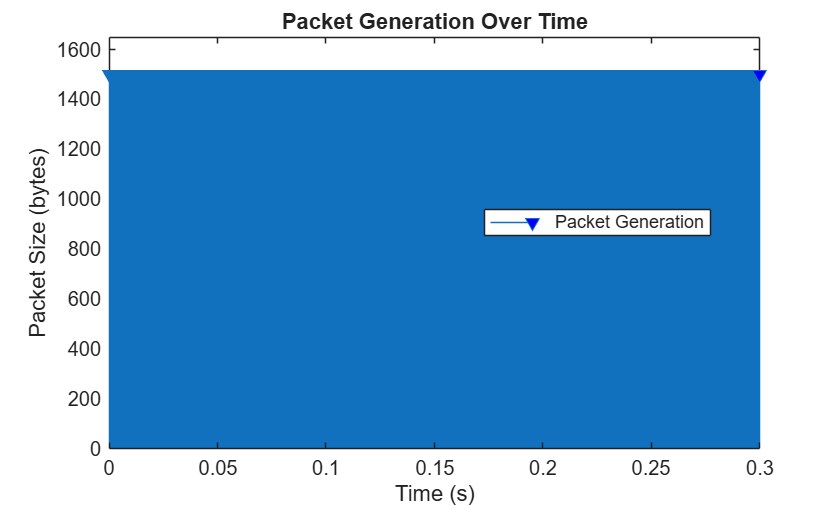

plotTrafficPattern(simulationTime,traffic);

# Task 5/7: Add traffic from gNB to UE

**Instructions to complete the task**

Use addTrafficSource() function to add application traffic to the nodes  

Type "doc addTrafficSource" in the MATLAB Command Window, and see the "Syntax" section.

Note : use the following values as arguments 

- gNB

- traffic

- "DestinationNode",UE

% <enter code below>
addTrafficSource(gNB,traffic,"DestinationNode",UE);

# Task 6/7: Add traffic from UE to gNB

**Instructions to complete the task**

Use addTrafficSource() function to add application traffic to the nodes  

Type "doc addTrafficSource" in the MATLAB Command Window, and see the "Syntax" section.

Note : use the following values as arguments 

- UE

- traffic

- "DestinationNode",gNB

% <enter code below>
addTrafficSource(UE,traffic,"DestinationNode",gNB);

#### Add nodes to the network simulator 

You can pass an array of gNBs and UEs to the addNode function  

addNodes(networkSimulator,gNB)
addNodes(networkSimulator,UE)

#### Add channel Model 

- The default channel model is Free Space Path Loss (FSPL).

- You can use prebuilt channel models for various deployment scenarios defined in 3GPP TR 38.901.

- Control whether small-scale fading is applied to interfering signals in the channel model.

- You also use custom channel models 

fsplOnly = true;
if ~fsplOnly
channel = h38901Channel(Scenario="UMa");
addChannelModel(networkSimulator,@channel.channelFunction);
connectNodes(channel,networkSimulator,InterfererHasSmallScale=true);
end

#### Enable visualization the network performance    

- Cell Performance Metrics – Shows key KPIs like throughput, fairness, and buffer status 

- RLC Metrics – Displays data transmitted at the RLC layer for each UE 

- BLER Metrics – Visualizes block error rates in uplink and downlink 

- Resource Grid Allocation – Shows time-frequency resource allocation and HARQ activity 

- Channel Quality – Displays CQI variations across time and frequency 

- Simulation Summary – Compares achieved performance with theoretical limits

**RefreshRate = 100** means that the visualizations are updated every **100 ms**.

metricsVisualizer = helperNRMetricsVisualizer(gNB,UE, ...
RefreshRate=100, ...
PlotSchedulerMetrics=true, ...
PlotPhyMetrics=true);

#### Set up the logger For logging the simulation traces

Enables or disables trace logging; disabling it improves simulation speed.

analyzeLogs = true;
if analyzeLogs
    simSchedulingLogger = helperNRSchedulingLogger(numFrameSimulation,gNB,UE);
    simPhyLogger = helperNRPhyLogger(numFrameSimulation,gNB,UE);
end

#### Capture IQ Samples

- Nodes capture signals only when they are receiving on their configured frequency 

- Captured data may include both desired and interfering signals 

- Samples are stored after passing through the channel 

- Zeros indicate periods with no reception

analyzeSignal = false;
if phyAbstraction == "full-phy" && analyzeSignal
    iqSampleObj = wirelessIQLogger(gNB);
end

# Task 7/7: Run the Simulation 

Runs the discrete-event simulator in MATLAB to execute the network model.

**Instructions to complete the task**

Use run() function to run the model    

Type `doc wirelessnetworksimulator.run` in the MATLAB Command Window, and see the "Syntax" section.

Note : use the following values as arguments 

- networkSimulator

- simulationTime

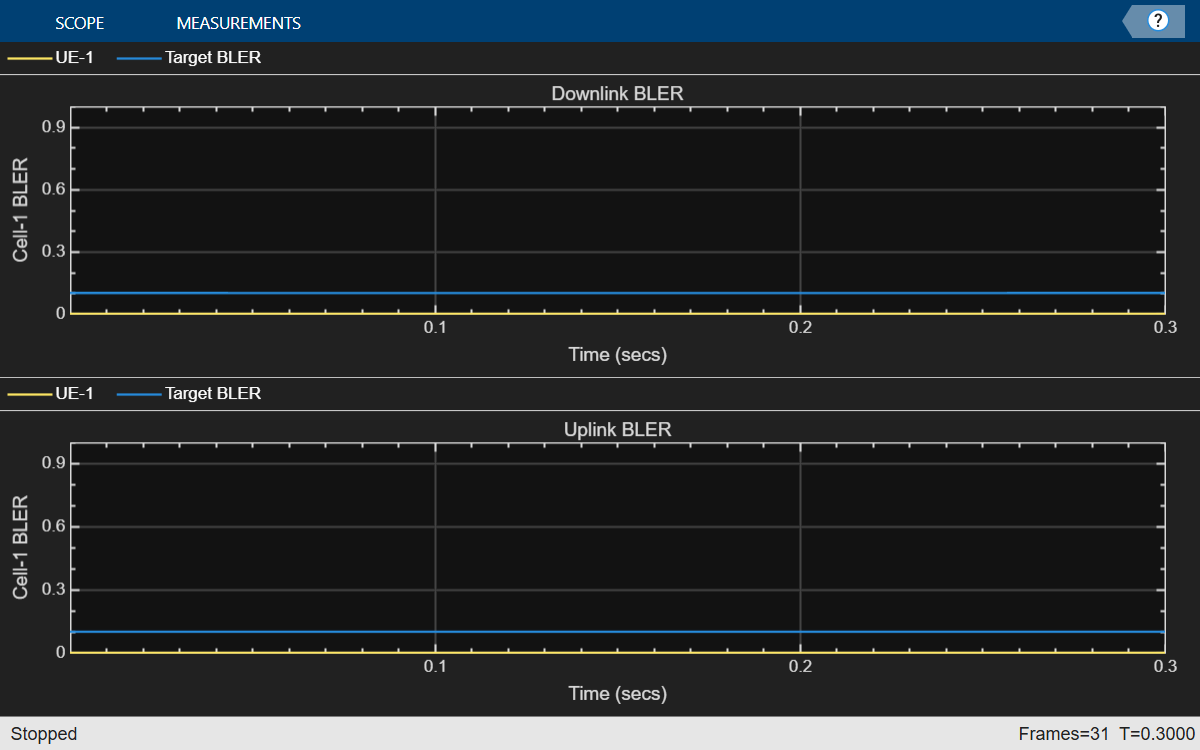

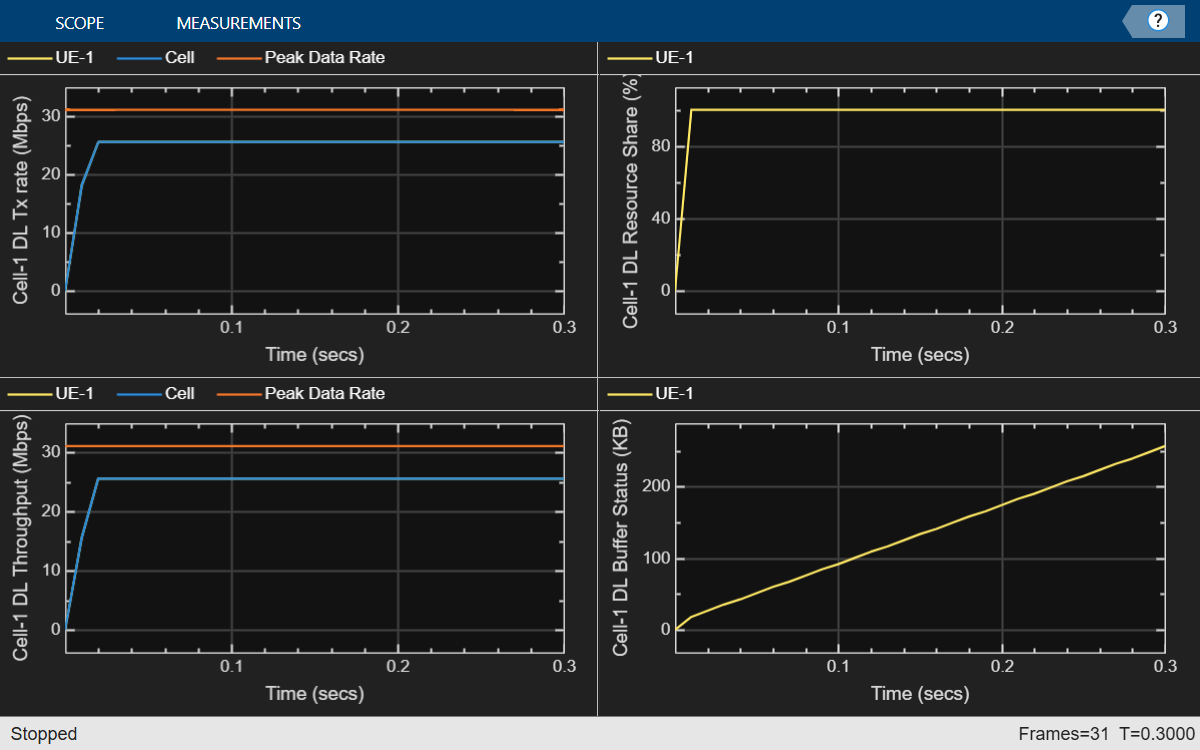

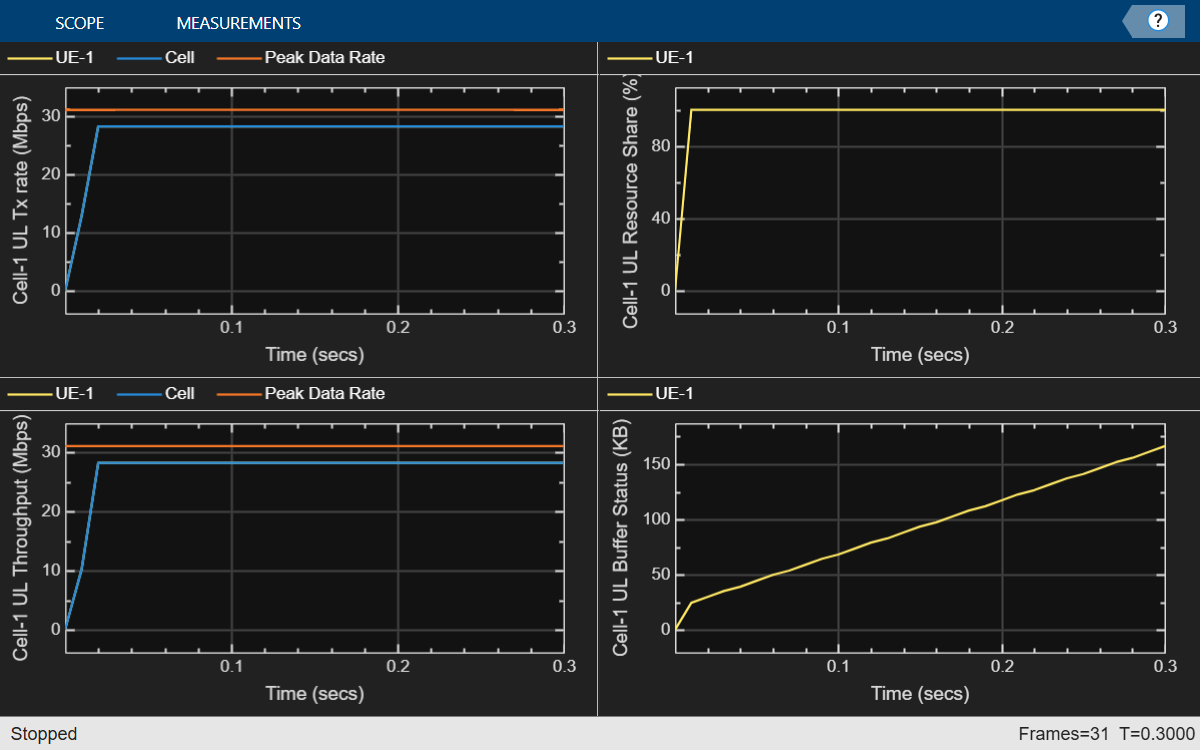

% <enter code below>
run(networkSimulator, simulationTime);

#### **Measure the Network Performance **

At the end of the simulation, compare the achieved system performance metrics with theoretical peak values (assuming zero overhead).

The displayed metrics include:

- Achieved data rate (UL and DL) 

- Achieved spectral efficiency (UL and DL) 

- Block error rate (BLER) for UEs (UL and DL) 

The theoretical peak values are calculated in accordance with 3GPP TR 37.910.

displayPerformanceIndicators(metricsVisualizer)

Peak UL throughput: 31.11 Mbps
Achieved cell UL throughput: 27.67 Mbps
Achieved UL throughput for each UE: [27.67]
Peak UL spectral efficiency: 6.22 bits/s/Hz
Achieved UL spectral efficiency for cell: 5.53 bits/s/Hz 
Block error rate for each UE in the UL direction: [0]

Peak DL throughput: 31.11 Mbps
Achieved cell DL throughput: 25.27 Mbps
Achieved DL throughput for each UE: [25.27]
Peak DL spectral efficiency: 6.22 bits/s/Hz
Achieved DL spectral efficiency for cell: 5.05 bits/s/Hz
Block error rate for each UE in the DL direction: [0]



### Print gNB statistics 

Some of the information captured across the APP, RLC, MAC, and PHY layers includes:

- Tx Packets 

- Rx Packets 

- Tx Bytes 

- Rx Bytes 

- Retransmitted Packets 

- Retransmitted Bytes 

- Decode Failures 

gnbStats = statistics(gNB);
gnbStats.MAC.Retransmissions

ans = 0

#### Print UE statistics 

ueStats = statistics(UE);
ueStats(1).MAC.Retransmissions

ans = 0

#### Capture Logs 

if analyzeLogs
    captureLogs(simSchedulingLogger,simPhyLogger,gNB);
end

#### NR Signal visualization

if phyAbstraction == "full-phy" && analyzeSignal
    fileName = iqSampleObj(1).FileName;
    iqData = load(fileName);
    signalAnalyzer(iqData.Waveform,SampleRate=iqData.Fs);
end


*Copyright 2025 The MathWorks, Inc.*